# PRÁCTICA RESOLUCIÓN NUMÉRICA DE SISTEMAS LINEALES

Programar los métodos de Gauss-Seidel y de Jacobi. 

Aplicar los programas desarrollados a los sistemas siguientes. Evaluamos con el vector estimación nulo y una tolerancia fija. Para cada uno comprobamos las dos condiciones siguientes:

- Sistema no singular.

- Sistema diagonalmente dominante.

e=1*10^-2;

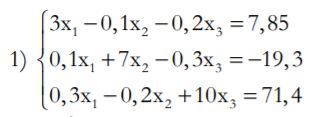

format long
A=[3 -0.1 -0.2; 0.1 7 -0.3; 0.3 -0.2 10]

A =    3.000000000000000  -0.100000000000000  -0.200000000000000
   0.100000000000000   7.000000000000000  -0.300000000000000
   0.300000000000000  -0.200000000000000  10.000000000000000


b=[7.85; -19.3; 71.4]

b =    7.850000000000000
 -19.300000000000001
  71.400000000000006


%Comprobamos que sea diagonalmenete dominante y det(A)>0.
diag_dominant=true;
for i=1:3
    diag_dominant=diag_dominant && (abs(2*A(i,i))>abs(sum(A(i,:))));
end
if(det(A)~=0 && diag_dominant)
    v1=[0 0 0] %Vector estimación inicial.
    [sol1Gauss_Seidel,sol_parcial1_gs,k1_gs]=gauss_seidel(A,b,e,v1)    
    [sol1Jacobi,sol_parcial1_j,k1_j]=jacobi(A,b,e,v1)
end

v1 =      0     0     0


sol1Gauss_Seidel =    2.990556507936508  -2.499624684807256   7.000290811065760


sol_parcial1_gs =                    0                   0                   0
   2.616666666666667  -2.794523809523810   7.005609523809524
   2.990556507936508  -2.499624684807256   7.000290811065760


k1_gs =      2


sol1Jacobi =    3.000806349206349  -2.499738435374149   7.000206666666668


sol_parcial1_j =                    0                   0                   0
   2.616666666666667  -2.757142857142857   7.140000000000001
   3.000761904761905  -2.488523809523810   7.006357142857143
   3.000806349206349  -2.499738435374149   7.000206666666668


k1_j =      3


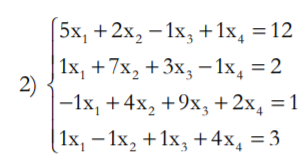

format long
B=[5 2 -1 1; 1 7 3 -1; -1 4 9 2; 1 -1 1 4]

B =      5     2    -1     1
     1     7     3    -1
    -1     4     9     2
     1    -1     1     4


c=[12; 2; 1; 3]

c =     12
     2
     1
     3


%Comprobamos que sea diagonalmenete dominante y det(B)>0.
diag_dominant=true;
for i=1:3
    diag_dominant=diag_dominant && (abs(2*B(i,i))>abs(sum(B(i,:))));
end
if(det(B)~=0 && diag_dominant)
    v2=[0 0 0 0] %Vector estimación inicial.
    [sol2Gauss_Seidel,sol_parcial2_gs,k2_gs]=gauss_seidel(B,c,e,v2)
    [sol2Jacobi,sol_parcial2_j,k2_j]=jacobi(B,c,e,v2)
end

v2 =      0     0     0     0


sol2Gauss_Seidel =    2.712047951707313  -0.391736044783814   0.625600449837565  -0.182346111582173


sol_parcial2_gs =                    0                   0                   0                   0
   2.400000000000000  -0.057142857142857   0.403174603174603   0.034920634920635
   2.496507936507936  -0.238730158730159   0.486843033509700  -0.055520282186949
   2.603964726631393  -0.302859158478206   0.547382436102013  -0.113551580302903
   2.653330466672266  -0.344147050754458   0.584113536699545  -0.145397763531567
   2.683561080348006  -0.368757064854030   0.605487207425251  -0.164451338156822
   2.701490535058026  -0.383200499355800   0.618132800977208  -0.175705958847759
   2.712047951707313  -0.391736044783814   0.625600449837565  -0.182346111582173


k2_gs =      7


sol2Jacobi =    2.377142857142857  -0.030952380952381   0.306790123456790   0.190079365079365


sol_parcial2_j =                    0                   0                   0                   0
   2.400000000000000   0.285714285714286   0.111111111111111   0.750000000000000
   2.157936507936508   0.002380952380952   0.084126984126984   0.193650793650794
   2.377142857142857  -0.030952380952381   0.306790123456790   0.190079365079365


k2_j =      3


Evaluamos los métodos con una matriz A' que no sea diagonalmente dominante y observamos qué pasa:

B2=[1 7 3 -1; 5 2 -1 1; -1 4 9 2; 1 -1 1 4]

B2 =      1     7     3    -1
     5     2    -1     1
    -1     4     9     2
     1    -1     1     4


c=[12; 2; 1; 3]

c =     12
     2
     1
     3


diag_dominantB2=true;
for i=1:3
    diag_dominantB2=diag_dominantB2 && (abs(2*B2(i,i))>abs(sum(B2(i,:))));
end
diag_dominantB2

diag_dominantB2 = logical
   0


[solB2Gauss_Seidel,sol_parcialB2_gs,kB2_gs]=gauss_seidel(B2,c,e,v2)    

solB2Gauss_Seidel =    NaN   NaN   NaN   NaN


sol_parcialB2_gs = 	1.0e+307 *

                   0                   0                   0                   0
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000


kB2_gs =    286


[solB2Jacobi,sol_parcialB2_j,kB2_j]=jacobi(B2,c,e,v2)

solB2Jacobi =   -Inf  -Inf   NaN   NaN


sol_parcialB2_j = 	1.0e+307 *

                   0                   0                   0                   0
   0.000000000000000   0.000000000000000   0.000000000000000   0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000
  -0.000000000000000  -0.000000000000000   0.000000000000000  -0.000000000000000
   0.000000000000000   0.000000000000000   0.000000000000000  -0.000000000000000


kB2_j =    494


Vamos a volver a evaluar los métodos con una tolerancia que irá variando.

format long
vector_e=[1,1*10^-2,1*10^-3,1*10^-5,1*10^-7,1*10^-10,1*10^-12]

vector_e =    1.000000000000000   0.010000000000000   0.001000000000000   0.000010000000000   0.000000100000000   0.000000000100000   0.000000000001000


%Método Gauss-Seidel
soluciones_sistema1_gaussSeidel = ones(7,3);
soluciones_sistema2_gaussSeidel = ones(7,4);

for i=1:length(vector_e)
    soluciones_sistema1_gaussSeidel(i,:)=gauss_seidel(A,b,vector_e(i),v1);
    soluciones_sistema2_gaussSeidel(i,:)=gauss_seidel(B,c,vector_e(i),v2);
end

soluciones_sistema1_gaussSeidel

soluciones_sistema1_gaussSeidel =    2.990556507936508  -2.499624684807256   7.000290811065760
   2.990556507936508  -2.499624684807256   7.000290811065760
   3.000031897910809  -2.499987992353051   6.999999283215615
   3.000000352469273  -2.500000035754606   6.999999988710830
   2.999999998055568  -2.500000000456044   7.000000000049212
   2.999999999988079  -2.499999999997720   7.000000000000403
   3.000000000000103  -2.499999999999984   6.999999999999997


soluciones_sistema2_gaussSeidel

soluciones_sistema2_gaussSeidel =    2.400000000000000  -0.057142857142857   0.403174603174603   0.034920634920635
   2.712047951707313  -0.391736044783814   0.625600449837565  -0.182346111582173
   2.725422695260373  -0.402545270462239   0.635055739669001  -0.190755926347903
   2.727256598799155  -0.404027369549657   0.636352234194074  -0.191909050635722
   2.727272586665605  -0.404040290406449   0.636363536960165  -0.191919103508055
   2.727272727123774  -0.404040403920025   0.636363636258333  -0.191919191825533
   2.727272727270528  -0.404040404038627   0.636363636362081  -0.191919191917809



%Método Jacobi
soluciones_sistema1_jacobi = ones(7,3);
soluciones_sistema2_jacobi = ones(7,4);

for i=1:length(vector_e)
    soluciones_sistema1_jacobi(i,:)=jacobi(A,b,vector_e(i),v1);
    soluciones_sistema2_jacobi(i,:)=jacobi(B,c,vector_e(i),v2);
end

soluciones_sistema1_jacobi

soluciones_sistema1_jacobi =    3.000761904761905  -2.488523809523810   7.006357142857143
   3.000806349206349  -2.499738435374149   7.000206666666668
   3.000806349206349  -2.499738435374149   7.000206666666668
   2.999998647316704  -2.500001133916424   6.999999271859411
   3.000000000797412  -2.499999997999337   7.000000002352559
   3.000000000004054  -2.500000000002504   6.999999999995083
   2.999999999999980  -2.500000000000001   7.000000000000007


soluciones_sistema2_jacobi

soluciones_sistema2_jacobi =    2.400000000000000   0.285714285714286   0.111111111111111   0.750000000000000
   2.377142857142857  -0.030952380952381   0.306790123456790   0.190079365079365
   2.724124820792421  -0.401137057260172   0.633303377290280  -0.188902332794328
   2.727246209893230  -0.404015946037356   0.636337857511719  -0.191893778039089
   2.727272431422000  -0.404040131165856   0.636363348752559  -0.191918908380055
   2.727272727009484  -0.404040403797605   0.636363636107725  -0.191919191666903
   2.727272727269790  -0.404040404037695   0.636363636360781  -0.191919191916377


Por último, para validar las soluciones obtenidas vamos a utilizar el comando **"** **\ "** que permite resolver sistemas de ecuaciones. Comparamos la solución obtenida con la exacta.

format long
sol_exacta1=(A\b)'

sol_exacta1 =    3.000000000000000  -2.500000000000000   7.000000000000002


sol_exacta2=(B\c)'

sol_exacta2 =    2.727272727272728  -0.404040404040404   0.636363636363636  -0.191919191919192


%Errores relativos
format long
errores_sistema1_gaussSeidel = ones(7,3);
errores_sistema2_gaussSeidel = ones(7,4);

errores_sistema1_jacobi = ones(7,3);
errores_sistema2_jacobi = ones(7,4);

for i=1:length(vector_e)
    errores_sistema1_gaussSeidel(i,:)= abs((sol_exacta1-soluciones_sistema1_gaussSeidel(i,:))./sol_exacta1);
    errores_sistema2_gaussSeidel(i,:)= abs((sol_exacta2-soluciones_sistema2_gaussSeidel(i,:))./sol_exacta2);
    errores_sistema1_jacobi(i,:)= abs((sol_exacta1-soluciones_sistema1_jacobi(i,:))./sol_exacta1);
    errores_sistema2_jacobi(i,:)= abs((sol_exacta2-soluciones_sistema2_jacobi(i,:))./sol_exacta2);
end

errores_sistema1_gaussSeidel

errores_sistema1_gaussSeidel =    0.003147830687831   0.000150126077098   0.000041544437965
   0.003147830687831   0.000150126077098   0.000041544437965
   0.000010632636936   0.000004803058780   0.000000102397770
   0.000000117489758   0.000000014301843   0.000000001612739
   0.000000000648144   0.000000000182418   0.000000000007030
   0.000000000003974   0.000000000000912   0.000000000000057
   0.000000000000034   0.000000000000006   0.000000000000001


errores_sistema2_gaussSeidel

errores_sistema2_gaussSeidel =    0.120000000000000   0.858571428571429   0.366439909297052   1.181954887218046
   0.005582417707318   0.030453289160062   0.016913578826684   0.049880787019203
   0.000678345071197   0.003700455605959   0.002055266234427   0.006061225871453
   0.000005913773643   0.000032260364599   0.000017917695026   0.000052841424398
   0.000000051555945   0.000000281244039   0.000000156205455   0.000000460668557
   0.000000000054616   0.000000000297938   0.000000000165478   0.000000000488013
   0.000000000000807   0.000000000004400   0.000000000002444   0.000000000007206


errores_sistema1_jacobi

errores_sistema1_jacobi =    0.000253968253968   0.004590476190476   0.000908163265306
   0.000268783068783   0.000104625850340   0.000029523809524
   0.000268783068783   0.000104625850340   0.000029523809524
   0.000000450894432   0.000000453566570   0.000000104020084
   0.000000000265804   0.000000000800265   0.000000000336080
   0.000000000001351   0.000000000001002   0.000000000000703
   0.000000000000007   0.000000000000001   0.000000000000001


errores_sistema2_jacobi

errores_sistema2_jacobi =    0.120000000000000   1.707142857142857   0.825396825396825   4.907894736842104
   0.128380952380952   0.923392857142857   0.517901234567901   1.990413533834586
   0.001154232376112   0.007185783281074   0.004808978543846   0.015719423861134
   0.000009723039149   0.000060533557545   0.000040509624442   0.000132419691064
   0.000000108478600   0.000000675364506   0.000000451960265   0.000001477388133
   0.000000000096523   0.000000000600929   0.000000000402147   0.000000001314557
   0.000000000001077   0.000000000006705   0.000000000004487   0.000000000014667


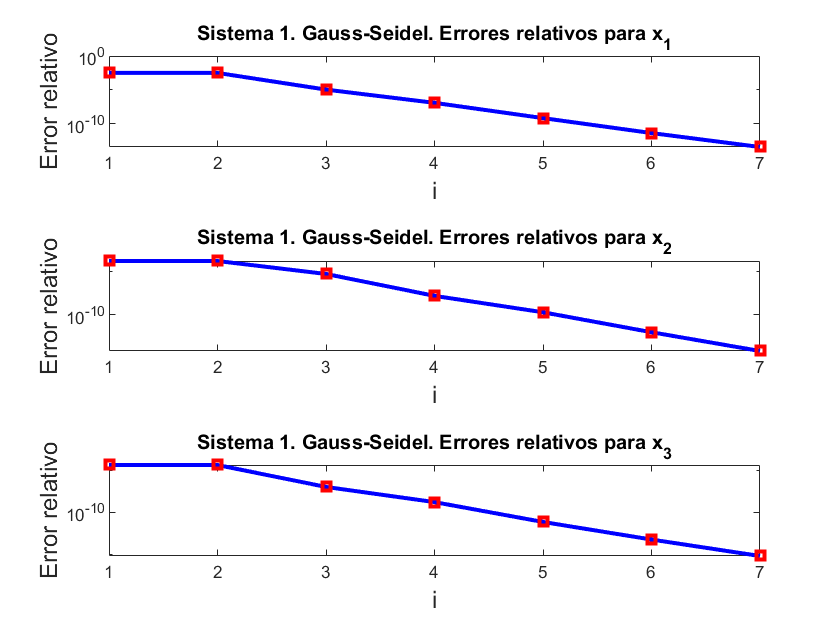


%SISTEMA 1
%Representamos los errores obtenidos para cada variable
%Gauss Seidel
t = tiledlayout(3,1);
nexttile
semilogy(errores_sistema1_gaussSeidel(:,1),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Gauss-Seidel. Errores relativos para x_1','FontSize',10)
nexttile
semilogy(errores_sistema1_gaussSeidel(:,2),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Gauss-Seidel. Errores relativos para x_2','FontSize',10)
nexttile
semilogy(errores_sistema1_gaussSeidel(:,3),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Gauss-Seidel. Errores relativos para x_3','FontSize',10)

%Jacobi
t = tiledlayout(3,1);

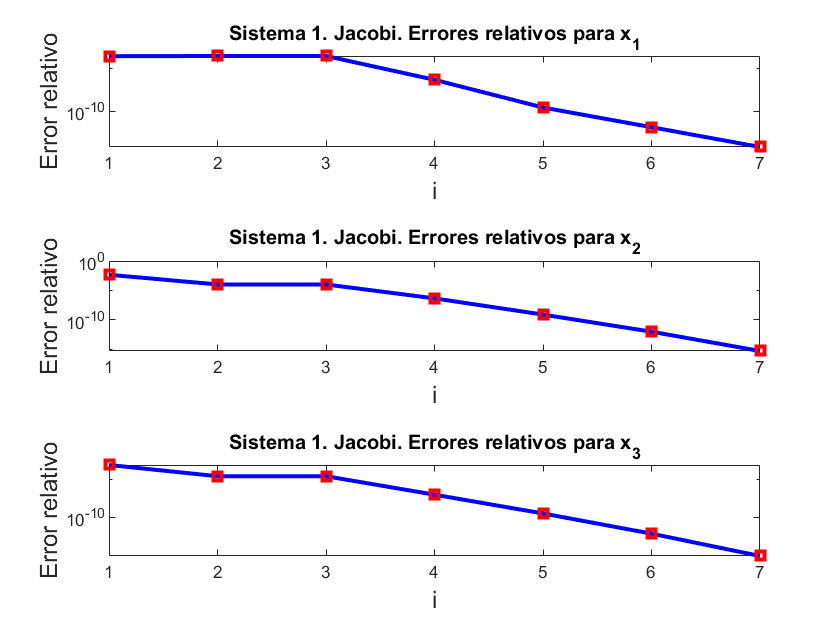

nexttile
semilogy(errores_sistema1_jacobi(:,1),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Jacobi. Errores relativos para x_1','FontSize',10)
nexttile
semilogy(errores_sistema1_jacobi(:,2),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Jacobi. Errores relativos para x_2','FontSize',10)
nexttile
semilogy(errores_sistema1_jacobi(:,3),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 1. Jacobi. Errores relativos para x_3','FontSize',10)


%SISTEMA 2
%Gauss-Seidel
t = tiledlayout(4,1);

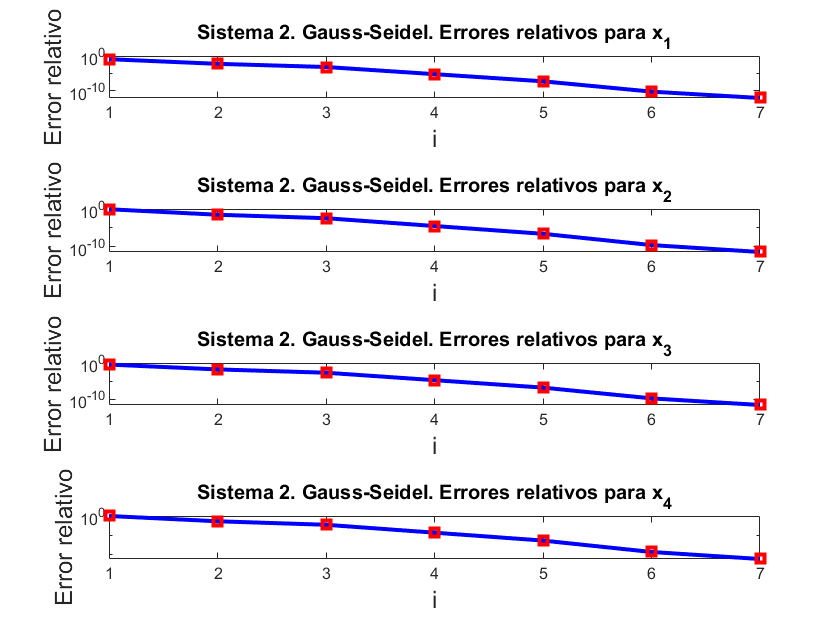

nexttile
semilogy(errores_sistema2_gaussSeidel(:,1),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Gauss-Seidel. Errores relativos para x_1','FontSize',10)
nexttile
semilogy(errores_sistema2_gaussSeidel(:,2),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Gauss-Seidel. Errores relativos para x_2','FontSize',10)
nexttile
semilogy(errores_sistema2_gaussSeidel(:,3),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Gauss-Seidel. Errores relativos para x_3','FontSize',10)
nexttile
semilogy(errores_sistema2_gaussSeidel(:,4),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Gauss-Seidel. Errores relativos para x_4','FontSize',10)

%Jacobi
t = tiledlayout(4,1);

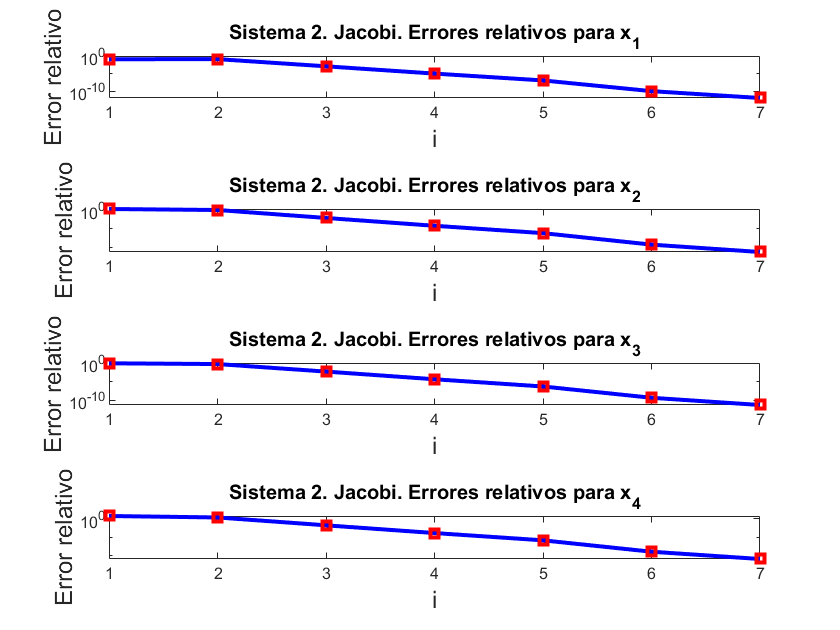

nexttile
semilogy(errores_sistema2_jacobi(:,1),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Jacobi. Errores relativos para x_1','FontSize',10)
nexttile
semilogy(errores_sistema2_jacobi(:,2),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Jacobi. Errores relativos para x_2','FontSize',10)
nexttile
semilogy(errores_sistema2_jacobi(:,3),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Jacobi. Errores relativos para x_3','FontSize',10)
nexttile
semilogy(errores_sistema2_jacobi(:,4),'-bs','LineWidth',2,'MarkerEdgeColor','r','MarkerSize',5)
xlabel('i',"FontSize",12)
ylabel('Error relativo','FontSize',12)
title('Sistema 2. Jacobi. Errores relativos para x_4','FontSize',10)